cd(fileparts(matlab.desktop.editor.getActiveFilename));
SNR = -15:5:5;
avg_nmse_oneshot = [];
avg_nmse_2step = [];
for snr = SNR
    snr_lin = 10^(snr/10);
    % noiseVar = 1/snr_lin;
    data = load(['generatedChannel_TDL_A_300_simple\SNR_', num2str(snr), 'dB\matlabNTN.mat']);
    nmse_oneshot_total = 0;
    nmse_2step_total = 0;
    for n = 1: size(data.H_perfect, 3)
        H_perf = data.H_perfect(:,:,n).';
        H_LS = data.H_ls(:,:,n).';
        [pilot_sub_idx, pilot_sym_idx] = find(H_LS~=0);
        pilot_sub_idx = unique(pilot_sub_idx);
        pilot_sym_idx = unique(pilot_sym_idx);

        H_LS_pilots = H_LS(pilot_sub_idx,pilot_sym_idx);

        channelPower = mean(abs(H_perf(:)).^2);
        % Scale the noise variance to match the channel's power
        scaledNoiseVar = channelPower / snr_lin;

        % --- APPROACH A: ONE-SHOT 2D LMMSE ---
        % vectorize the whole grid and the pilots
        H_vec = H_perf(:);
        H_LS_vec = H_LS_pilots(:);
        
        % Calculate Correlation Matrices
        % Divide by the number of samples to keep the scale consistent
        R_all_pilots = (H_vec * H_LS_pilots(:)');         % Cross-correlation     % R_hy
        R_pilots_pilots = (H_LS_pilots(:) * H_LS_pilots(:)'); % Auto-correlation  % R_yy
        
        W_oneshot = R_all_pilots * inv(R_pilots_pilots + scaledNoiseVar * eye(size(R_pilots_pilots)));  % R_hy * inv(R_yy+N)
        H_oneshot_vec = W_oneshot * H_LS_vec;  % R_hy * inv(R_yy+N) * Y   % = R_hh* X^H * inv(X*R_hh*X^H + N) * Y
        H_oneshot = reshape(H_oneshot_vec, size(H_perf,1), size(H_perf,2));

        nmse_oneshot = (norm(H_perf(:) - H_oneshot(:))^2) / (norm(H_perf(:))^2);
        nmse_oneshot_total = nmse_oneshot_total + nmse_oneshot;
        
        % --- APPROACH B: 2-STEP (SEPARABLE) LMMSE ---
        % Step 1: Frequency-only LMMSE on symbols containing pilots
        H_step1 = zeros(size(H_perf,1), length(pilot_sym_idx));
        for i = 1:length(pilot_sym_idx)
            R_f = H_perf(:, pilot_sym_idx(i)) * H_perf(pilot_sub_idx, pilot_sym_idx(i))';
            R_ff = H_perf(pilot_sub_idx, pilot_sym_idx(i)) * H_perf(pilot_sub_idx, pilot_sym_idx(i))';
            W_f = R_f * inv(R_ff + scaledNoiseVar * eye(length(pilot_sub_idx)));
            H_step1(:, i) = W_f * H_LS_pilots(:, i);
        end

        % Step 2: Time-only LMMSE (Interpolate across symbols)
        H_2step = zeros(size(H_perf));
        for k = 1: size(H_perf,1)
            % 1. Cross-correlation: All symbols (1:M) vs Pilot symbols
            % Result: (M x length(pilot_sym_idx))
            R_t = H_perf(k, :).' * H_perf(k, pilot_sym_idx); 
            
            % 2. Auto-correlation: Pilot symbols vs Pilot symbols
            % Result: (length(pilot_sym_idx) x length(pilot_sym_idx))
            R_tt = H_perf(k, pilot_sym_idx).' * H_perf(k, pilot_sym_idx);
            
            % 3. LMMSE Weight Matrix
            W_t = R_t * inv(R_tt + scaledNoiseVar * eye(length(pilot_sym_idx)));
            
            % 4. Estimate the full row for subcarrier k
            % H_step1(k, :) contains the frequency-cleaned estimates at pilot times
            H_2step(k, :) = (W_t * H_step1(k, :).').';
        end
        nmse_2step = (norm(H_perf(:) - H_2step(:))^2) / (norm(H_perf(:))^2);
        nmse_2step_total = nmse_2step_total+ nmse_2step;
    end
    avg_nmse_oneshot = [avg_nmse_oneshot nmse_oneshot_total/size(data.H_perfect, 3)];
    avg_nmse_2step = [avg_nmse_2step nmse_2step_total/size(data.H_perfect, 3)];
end
avg_nmse_oneshot

avg_nmse_oneshot =     0.0049    0.0019    0.0004    0.0000    0.0000


avg_nmse_2step

avg_nmse_2step =     1.0013    1.0217    2.0861    3.5330    0.3404


avg_nmse_li = [];
for snr = SNR
    data = load(['generatedChannel_TDL_A_300_simple\SNR_', num2str(snr), 'dB\matlabNTN.mat']);
    avg_nmse_li = [avg_nmse_li data.nmse_li];
end
avg_nmse_li

avg_nmse_li =     3.4112    1.1630    0.4406    0.2159    0.1433


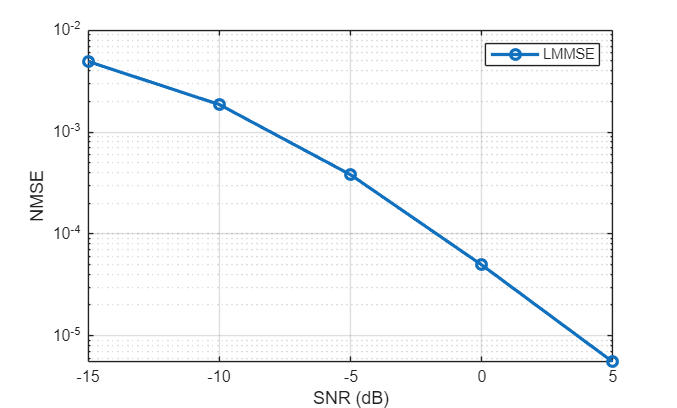

avg_nmse_oneshot = [49.3115e-4 18.6093e-4 3.8028e-4 4.9415e-05 5.4983e-06];
avg_nmse_2step = [1.0013    1.0217    2.0861    3.5330    0.3404];
figure; semilogy(SNR, avg_nmse_oneshot, 'LineWidth', 2, 'Marker','o'); 
xlabel('SNR (dB)');
ylabel('NMSE');
legend('LMMSE');
grid on

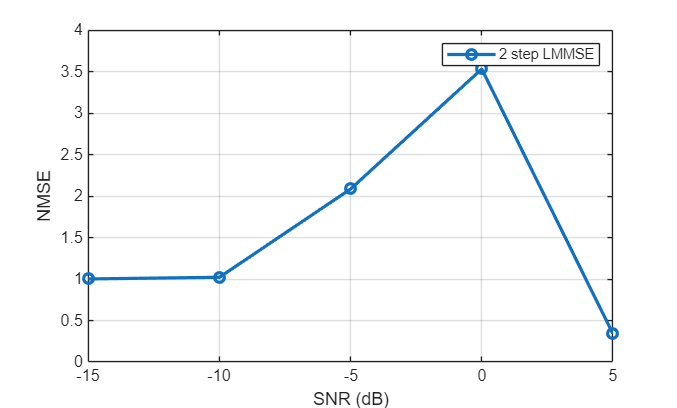


figure; plot(SNR, avg_nmse_2step,  'LineWidth', 2, 'Marker','o'); 
xlabel('SNR (dB)');
ylabel('NMSE');
legend('2 step LMMSE');
grid on